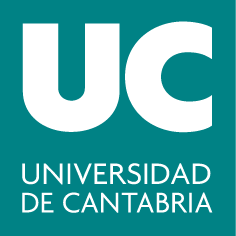

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 12: Diagonalización**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Objetivos**

- Cálculo de autovalores y autovectores

- Diagonalización

**Cálculo de autovalores y autovectores**

Imaginemos que tenemos el siguiente endomorfismo:


$$\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^3 \\
(x,y,z) \leadsto (3x-3z, 3y+9z, -3z) $$


Comenzaremos por definir la matriz asociada a $f$ en la base canónica (matriz estándar):

A = [3 0 -3; 0 3 9; 0 0 -3];  % matriz estándar de f

Para hallar los autovalores de $f$ (o $A$), podemos recurrir a la función *eig*:

autoval = eig(A)

Vemos que $f$ tiene como autovalores $\lambda=3$ (doble) y $\lambda=-3$ (simple). El siguiente paso sería calcular los subespacios propios asociados a estos autovalores, para lo cual tendremos que resolver el sistema homogéneo con matriz de coeficientes $A-\lambda_{i} I$, donde $\lambda_i = \lbrace 3, -3 \rbrace$. La solución a este sistema nos da directamente una base del subespacio propio asociado a $\lambda_i$:

% Subespacio propio asociado al autovalor 3 
baseV3 = null(A - autoval(1)*eye(3), 'r')  % dim(V3)=2=m(3)
% Subespacio propio asociado al autovalor -3 
baseVmenos3 = null(A - autoval(3)*eye(3), 'r')  % dim(Vmenos3)=1=m(-3)

**Diagonalización**

Para que un endomorfismo en un espacio vectorial real sea diagonalizable han de cumplirse dos condiciones:

- Todos sus autovalores tienen que ser reales

- La dimensión de cada subespacio propio tiene que coincidir con la multiplicidad (algebraica) del autovalor al que está asociado

En nuestro ejemplo, podemos ver que estos dos puntos se cumplen. Por tanto, $f$ será diagonalizable. Como ya sabemos, diagonalizar $f$ consiste en encontrar una matriz diagonal $D$ y otra $P$ tales que $A=PDP^{-1}$. La diagonal de $D$ estará formada por los autovalores de $f$ y $P$ contendrá en sus columnas una base de autovectores de $f$ del espacio en el que estemos trabajando, en este caso $\mathbb{R}^3$. Como sabes, ha de respetarse el mismo orden al colocar los valores propios en la diagonal de $D$ y los correspondientes vectores propios en las columnas de $P$.

D = diag(autoval)
P = [baseV3 baseVmenos3]

Podemos comprobar fácilmente que, efectivamente, la unión de las bases de los subespacios propios encontrados forman una base (de autovectores de $f$) de $\mathbb{R}^3$:

rank(P)  % los tres vectores son L.I. -> forman base de R³

La comprobación de que las matrices $D$ y $P$ que hemos obtenido son las correctas sería la siguiente:

A - P*D*inv(P)

Otra comprobación equivalente en la que evitamos el cálculo de inversas (muy conveniente para el tratamiento de problemas "a mano") sería la siguiente:

A*P - P*D

Además de los autovalores del endomorfismo, la función *eig *permite también hallar sus autovectores asociados del siguente modo:

[P2, D2] = eig(A)

La matriz $D2$ es la $D$ que habíamos obtenido anteriormente, es decir, la matriz que contiene en su diagonal los autovalores de $A$. Por su parte, $P2$ es una matriz cuyas columnas están formadas por autovectores de $A$ (lógicamente, la primera/segunda/tercera columna de $P2$ corresponde al autovector asociado al autovalor que se sitúa en la primera/segunda/tercera columna de $D2$). Sin embargo, fíjate que esta matriz $P2$ no coincide con la $P$ que habíamos obtenido anteriormente. Los autovectores que devuelve la función *eig *son todos unitarios.

norm(P2(:,1))  % norma 1
norm(P2(:,2))  % norma 1
norm(P2(:,3))  % norma 1

***Importante*****:** Ten en cuenta que el hecho de que el comando *eig *devuelva dos matrices no implica necesariamente que el endomorfismo con el que se esté trabajando sea diagonalizable. Por ejemplo, imagina que quisiéramos diagonalizar la matriz $A=\left\lbrack \begin{array}{ccc}
2 & 1 & 0\\
0 & 2 & 1\\
0 & 0 & 2
\end{array}\right\rbrack$:

A = [2 1 0; 0 2 1; 0 0 2];  % matriz estándar
[P, D] = eig(A)  % autovalores y autovectores

Aparentemente, ya tendríamos dos matrices $D$ y $P$ necesarias para diagonalizar $A$. Sin embargo, estas matrices no satisfacen la relación $A=PDP^{-1}$:

A - P*D*inv(P)

Y esto ocurre porque $P$ es una matriz singular ($det(P)=0$). En otras palabas, las columnas de $P$ no forman una base de autovectores de $f$, por lo que $A$ no es diagonalizable. En efecto, podemos ver que la dimension del subespacio propio asociado al autovalor $2$ (triple) no coincide con su multiplicidad algebraica.

baseV2 = null(A-2*eye(3), 'r')  % dim(V2)=1, m(2)=3
rank(A-2*eye(3))  % dim(V2) = 3-rg(A-2*I)

#### Ejercicios propuestos

**Ejercicio 1:**

Comprueba si el siguiente endomorfismo es diagonalizable:


$$\mathit{f}: \mathbb{R}^4 \longrightarrow  \mathbb{R}^4 \\
(x,y,z,t) \leadsto (x-2y, y-z, z+t, -3t) $$


**Ejercicio 2:**

Dada una aplicación lineal $\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^3$ cuyo $Ker(f) = <(1,2,0), (0,3,1)>$ y bajo la cual cualquier vector de la forma $(\alpha,0,0)$ se transforma en el $(0,0,\alpha)$, con $\alpha \in \mathbb{R}$:

- *a) *Halla su matriz estándar $A$

- *b)* Obtén una base de la imagen de $f$

- *c) *Obtén una base de la imagen del subespacio $S$ de $\mathbb{R}^3$ cuya forma paramétrica es $(\alpha, -\beta, \alpha+\beta)$, con $\alpha, \beta \in \mathbb{R}$

- *d) *Obtén una base de la imagen del subespacio $T$ de $\mathbb{R}^3$ cuya ecuación implícita es $x  = \frac{1}{2}y$

- *e)* Calcula los autovalores y autovectores de $f$

- *f)* En caso de existir, da una base de $\mathbb{R}^3$ formada por autovectores de $f$. ¿Cuál será la matriz de $f$ en esta base?

- *g)* Obtén $M$, la matriz de $f$ en la base $B=\lbrace (1 ,0,-3), (0,-2,1), (-1,1,0) \rbrace$

- *h)* ¿Qué relación existe entre la traza y el determinante de $A$ y $M$?

**Ejercicio 3:**

Dado el endoformismo $f$ cuya matriz estándar es la siguiente:


$$A=\left\lbrack \begin{array}{ccc}
-2 & 6 & 3\\
6 & 3 & -2\\
3 & -2 & 6
\end{array}\right\rbrack$$


- *a)* Clasifica $f$

- *b)* Comprueba si $f$ es diagonalizable. En caso de serlo, encuentra dos matrices $D$ y $P$ tales que $A=PDP^{-1}$ 

- *c)* ¿Qué tienen de particular los subespacios propios de $f$?

- *d)* Encuentra una base de $\mathbb{R}^3$ formada por autovectores unitarios de $f$. ¿Cuáles son las coordenadas del vector $(0,-4,1)$ respecto a esa base?